# Project software:  Selecting data

These are utilities to help you read data from the Macbeth Color Checker.  The utilities are useful, but you do need to be careful.  Sometimes the selection routines can miss by a bit.  So please check as you go along.

Please make sure you have done a git pull on the psych221 and ISETCam repositories.

## Reading data from the 24 patches

ISETCam has routines to help you retrieve data from a Macbeth color checker (MCC).  The selection routines were designed to work with an MCC that looks like this.

scene = sceneCreate;
sceneWindow(scene);

There are many MCCs, however, that have black borders around the patches. Also, many of the images we acquire are not perfectly squared up.  So I have been trying to update the methods to handle these cases. Here is an an example of an MCC black border.  

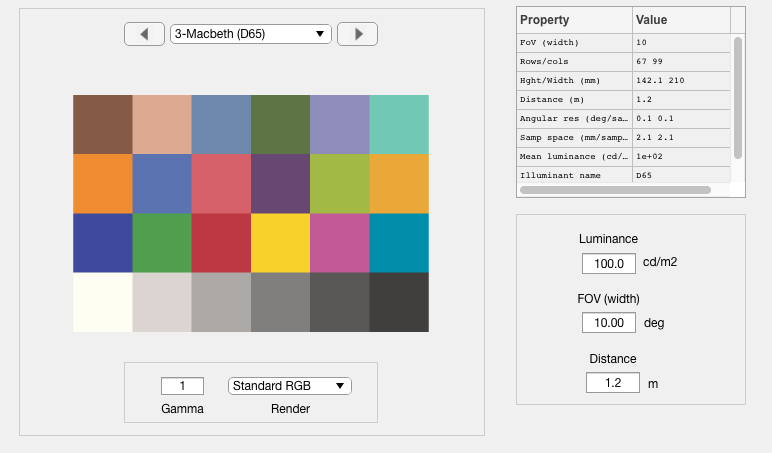

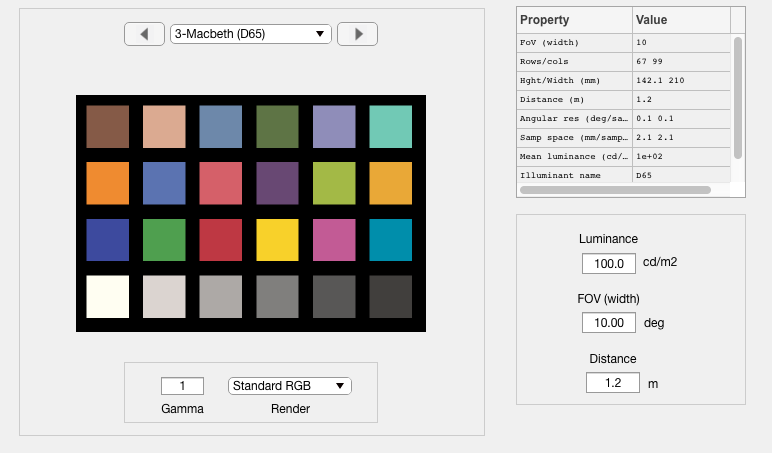

patchSizePixels = 16; wave = (400:10:700); 
blackBorder = true;
scene = sceneCreate('macbeth d65',patchSizePixels,wave,...
    'macbethChart.mat',blackBorder);
sceneWindow(scene);

**Note:** In ISETCam, we number the patches starting at the upper left corner (brown, (1,1)) and counting down the rows (orange, blue, white).  So the white patch at location (4,1) is patch number 4.

## Reading data from the patches

The methods to select and read data from the chart, in any of the windows, is are to (a) select the corner points, (b) check the derived rectangular patches, and (c) retrieve the data from the rectangular regions.   

When the MCC has black borders, we treat the effective patches as shown in these white dashed squares.  To make things work out, you must indicate there is a black border in input arguments, and then select the corner points as shown by the points in the red circles.

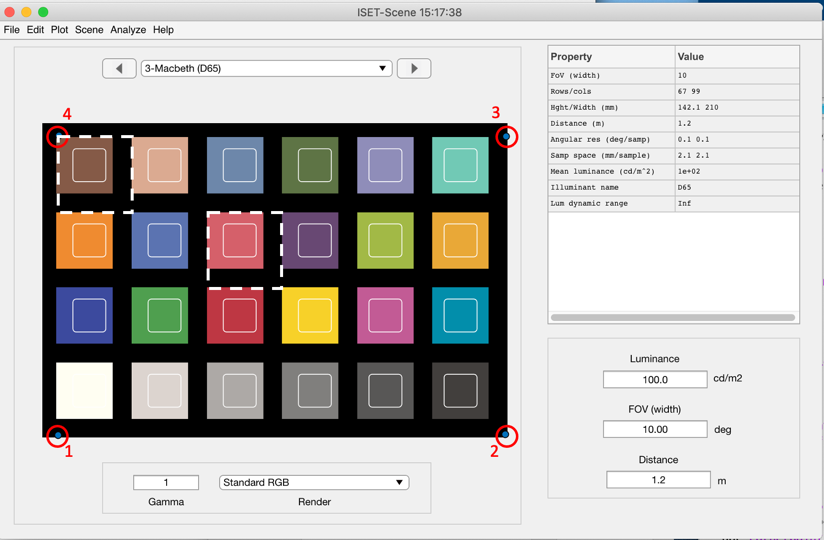

cp = chartCornerpoints(scene);
[rects, mLocs, pSize] = chartRectangles(cp,4,6,0.5,true);

Black border


chartRectsDraw(scene,rects);
nPixels = round(pSize(1)/5);  % Choose the central 20% of the pixels
fullData = false;
meanRadiance = chartRectsData(scene,mLocs,nPixels,fullData);

The data are returned in ISETCam XW format, in which spatial position is in the rows and wavelength in the columns.  We plot the radiances from each patch this way

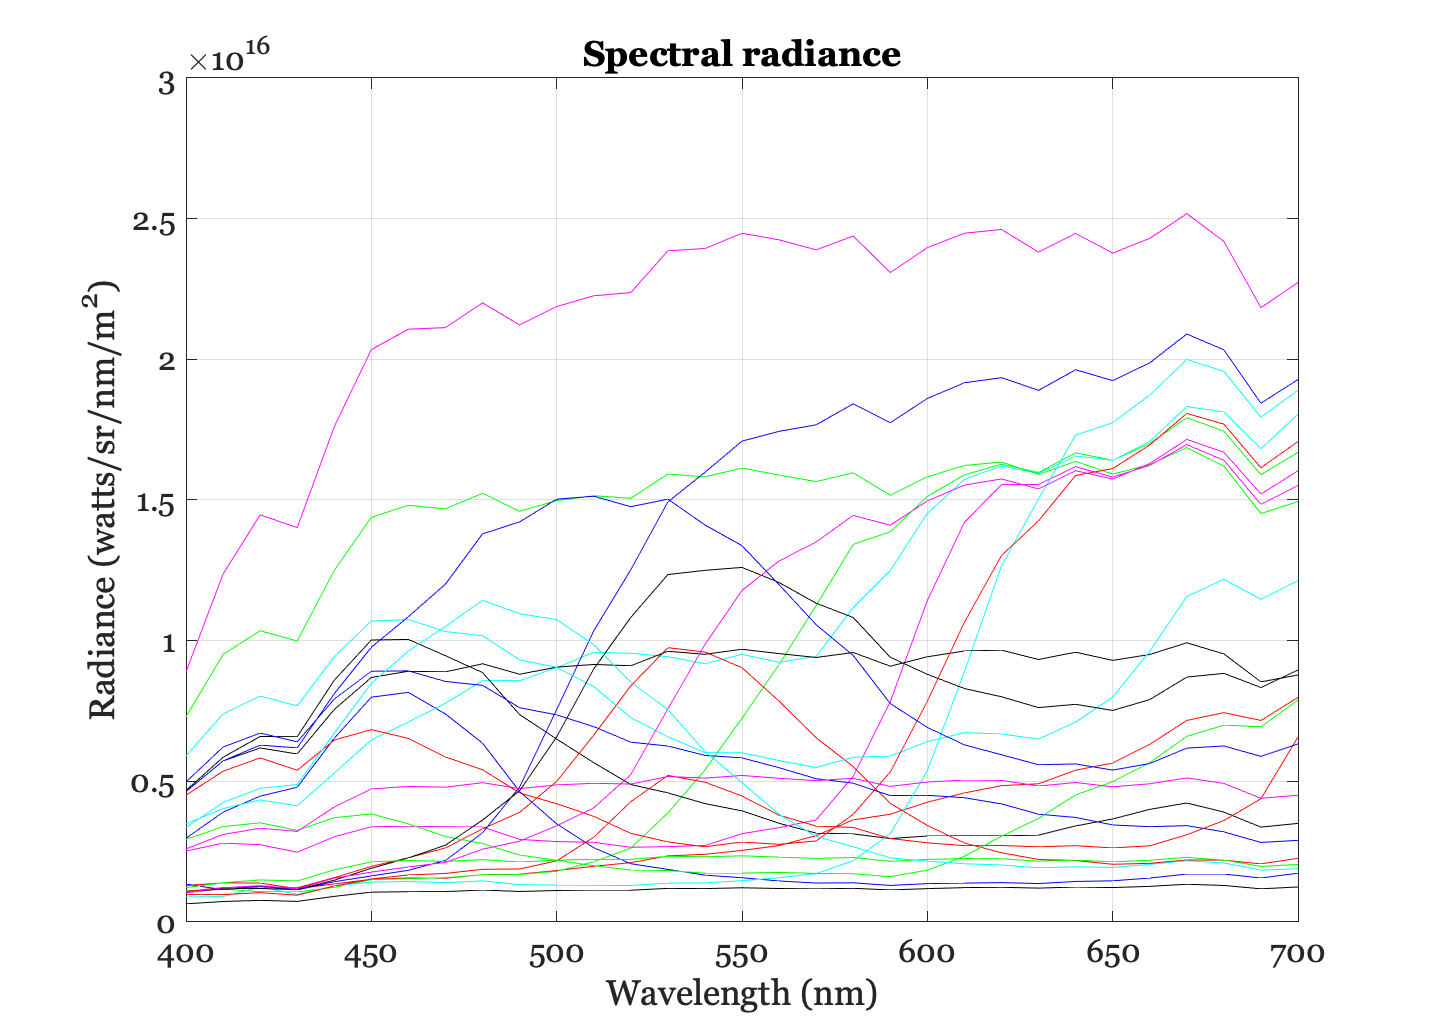

wave = sceneGet(scene,'wave');
meanRadiance = meanRadiance';
plotRadiance(wave,meanRadiance);

## Compute sensor data

The idea is pretty much identical in the sensor window, but the returned data differ.  here is an example.  We compute the sensor data this way.

oi = oiCreate;
oi = oiCompute(oi,scene);
sensor = sensorCreate;
sensor = sensorSet(sensor,'fov',sceneGet(scene,'fov'),oi);
sensor = sensorCompute(sensor,oi);
sensorWindow(sensor);

## Select sensor data

Next select the corner points in the sensor window, and check the rectanglepositions.  It is a bit tricky to select the proper corners (sorry).  Also, notice that we use 'sensor', not 'scene' as the argument to chart functions.

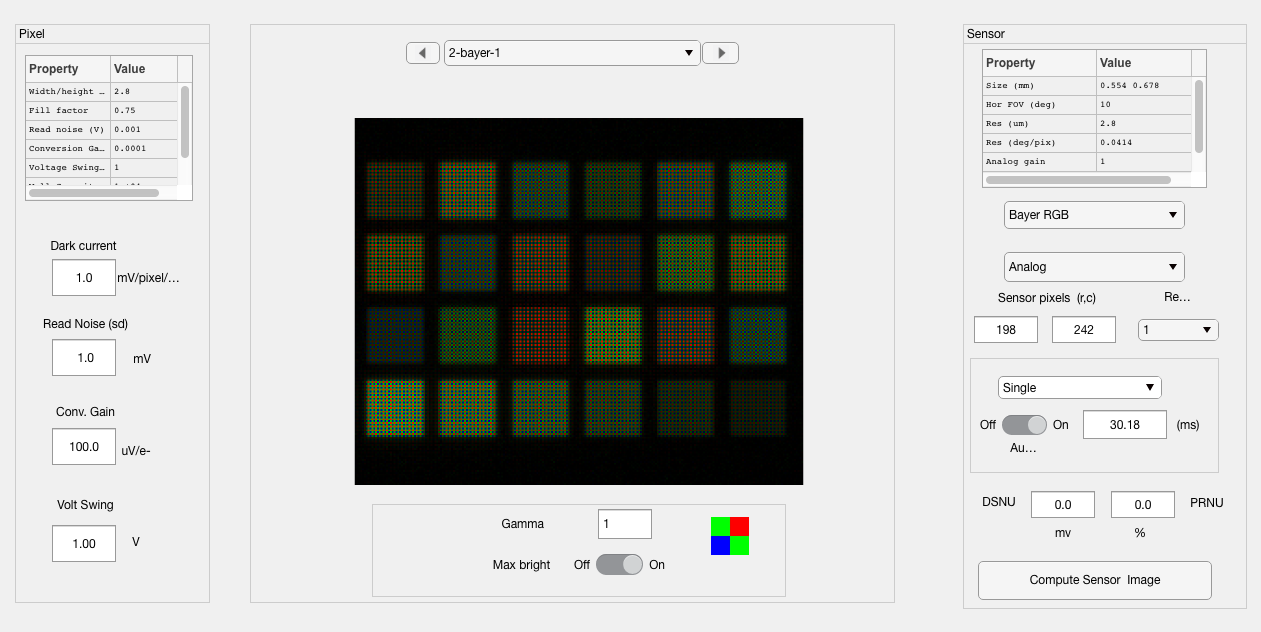

cp = chartCornerpoints(sensor);

[rects, mLocs, pSize] = chartRectangles(cp,4,6,0.5,true);

Black border


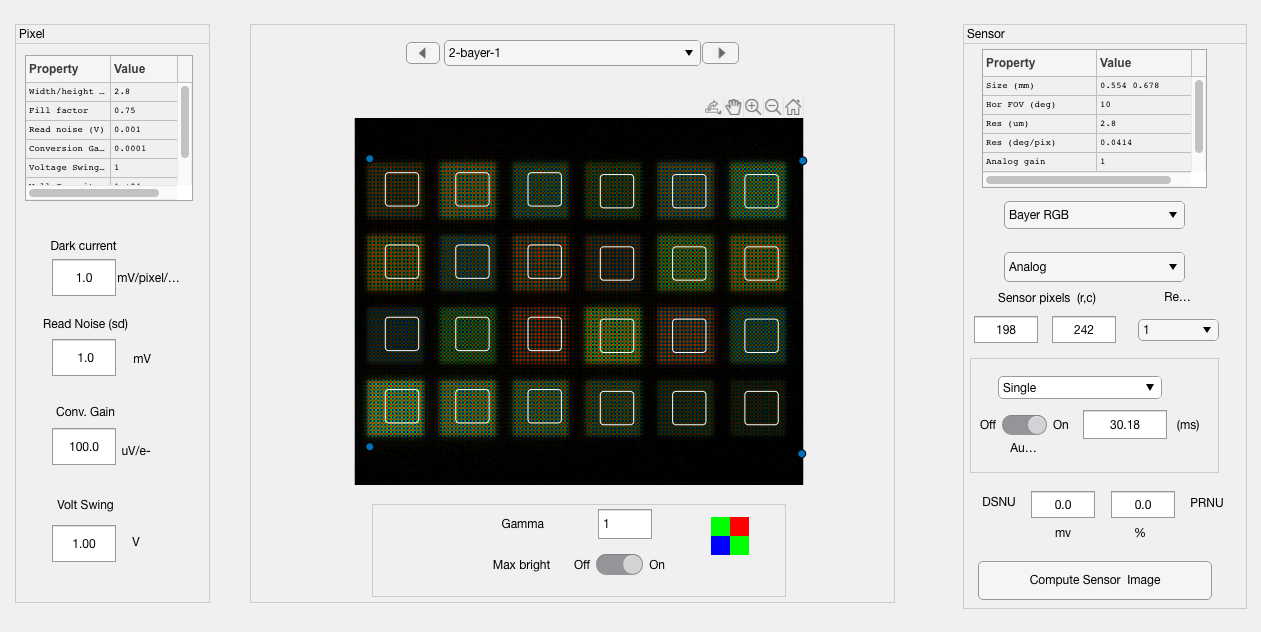

chartRectsDraw(sensor,rects);

nPixels = round(pSize(1)/5);  % Choose the central 20% of the pixels

fullData = false;   % The mean value of each patch is returned
dataType = 'volts';
meanVolts = chartRectsData(sensor,mLocs,nPixels,fullData,dataType);

## Selecting full data

Up to this point we set fullData to false, and the returned values were the mean levels in each patch.  If you set fullData to true, then the returned values  from each patch will be the data from each point, not just the mean.

fullData = true;         % Data from each pixel in each patch is returned
dataType = 'electrons';  % I changed to electrons because I was bored.
electrons = chartRectsData(sensor,mLocs,nPixels,fullData,dataType);

% In this case the format of the data is more complex because of the
% mosaic.  For example, here are the data from the 11th (red) patch at
% (3,3). There are lots of 'red' electrons
redPatch = electrons{11};
r = redPatch(:,1); disp(r(~isnan(r)));
g = redPatch(:,2); disp(g(~isnan(g)));
b = redPatch(:,3); disp(b(~isnan(b)));

% In the blue patch (3,1) there are more blue electrons
bluePatch = electrons{3};
r = bluePatch(:,1); disp(r(~isnan(r)));
g = bluePatch(:,2); disp(g(~isnan(g)));
b = bluePatch(:,3); disp(b(~isnan(b)));

## Without black borders

For completeness - and often used in simulations - here is a picture of how to select the corner points when the MCC has no black border.

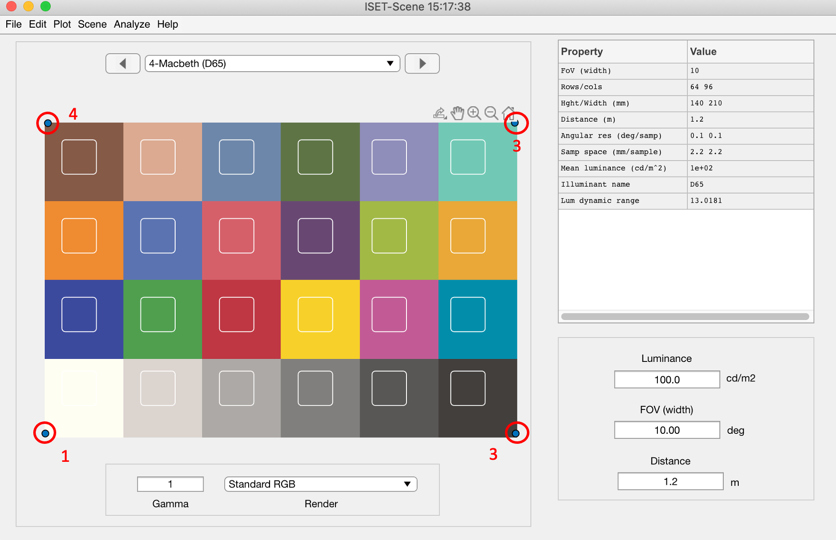

scene = sceneCreate;
cp = chartCornerpoints(scene);
[rects, mLocs, pSize] = chartRectangles(cp,4,6,0.5,true);

Black border


chartRectsDraw(scene,rects);
nPixels = round(pSize(1)/5);  % Choose the central 20% of the pixels
fullData = false;
meanRadiance = chartRectsData(scene,mLocs,nPixels,fullData);